%BATES method Vanilla option pricing K.tomov 

%Parameters

AssetPrice = 80;
Rate = 0.05;
DividendYield = 0.00;
OptSpec = 'call';

%Optionpricing (non-calibrated > Finite differences or Monte carlo can be
%used)

V0 = 0.06;%vol
ThetaV = 0.05;
Kappa = 1.0;
SigmaV = 0.2;
RhoSV = 0.7;
MeanJ = 0.2;
JumpVol = 0.08;
JumpFreq = 4;

%single strike computation

Settle = datetime(2024,6,29);
Maturity = datemnth(Settle, 12);
Strike = 80; 

Call = optByBatesNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, V0, ...
    ThetaV, Kappa, SigmaV, RhoSV, MeanJ, JumpVol, JumpFreq, ...
    'DividendYield', DividendYield)

Call = 16.7292

%vector strike price computation

Settle = datetime(2017,6,29);
Maturity = datemnth(Settle, 12);
Strike = (76:2:84)';

Call = optByBatesNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, V0, ...
    ThetaV, Kappa, SigmaV, RhoSV, MeanJ, JumpVol, JumpFreq, ...
    'DividendYield', DividendYield)

Call =    18.3933
   17.5406
   16.7292
   15.9573
   15.2231



%surface expansion Matric of call outputs

Call = optByBatesNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, V0, ...
    ThetaV, Kappa, SigmaV, RhoSV, MeanJ, JumpVol, JumpFreq, ...
    'DividendYield', DividendYield, 'ExpandOutput', true) % (5 x 5) matrix output

Call =    18.3933
   17.5406
   16.7292
   15.9573
   15.2231


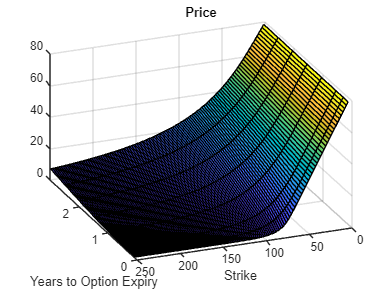

%plotingsurface

Settle = datetime(2023,6,29);
Maturity = datemnth(Settle, 12*[1/12 0.25 (0.5:0.5:3)]');
Times = yearfrac(Settle, Maturity);
Strike = (2:2:250)';

Call = optByBatesNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, V0, ...
    ThetaV, Kappa, SigmaV, RhoSV, MeanJ, JumpVol, JumpFreq, ...
    'DividendYield', DividendYield, 'ExpandOutput', true);


[X,Y] = meshgrid(Times,Strike);

figure;
surf(X,Y,Call);
title('Price');
xlabel('Years to Option Expiry');
ylabel('Strike');
view(-112,34);
xlim([0 Times(end)]);
zlim([0 80]);